# Categorical

% Load PLSR results. 
load('Y:\Sarah\Analysis\Experiments\Random Motorized Treadmill\PLSR\results\level 1 categorical\Ipsa Contra\motorized_restvswalk\1096\PLSR_results.mat');

% Load dataset
load('Y:\Sarah\Analysis\Experiments\Random Motorized Treadmill\PLSR\variable prep\datasets\level 1 categorical\Ipsa Contra\motorized_restvswalk\1096\PLSR_dataset_info.mat')

holder = NaN(32);
indices = find(tril(ones(32), -1));


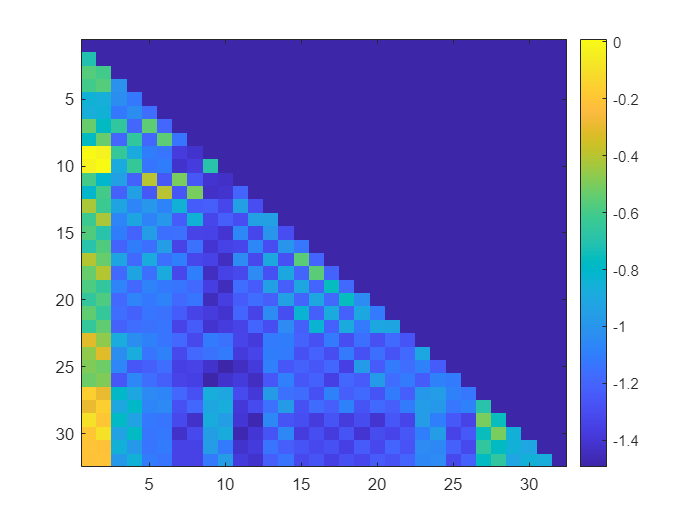


% Calculate & plot the mean difference between the two periods
% just averages from the original (normalized) dataset.

% (FYI, PLSR captures ~98% of the variation in the correlations for this
% comparison.)
mean_rest = mean(dataset_info.explanatoryVariables(dataset_info.responseVariables(:,2) < 0, :),1);
mean_walk = mean(dataset_info.explanatoryVariables(dataset_info.responseVariables(:,2) > 0, :),1);
mean_cat_diff_real = mean_walk - mean_rest;
holder(indices) = mean_cat_diff_real;
figure; imagesc(holder); colorbar;

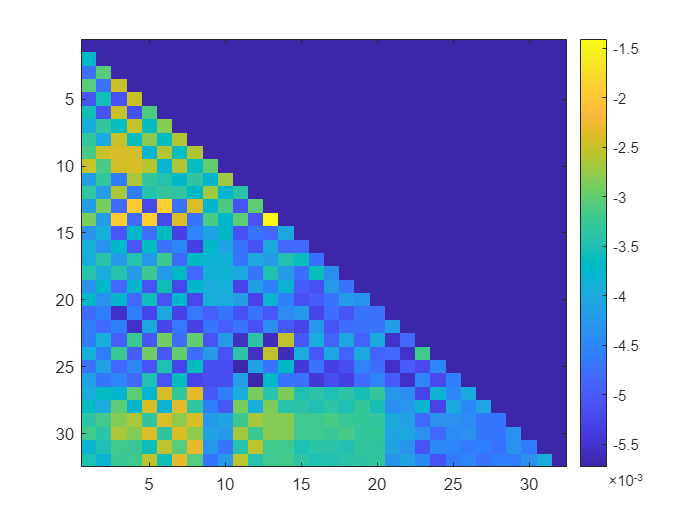

% For walk variable, plot PLSR calculated Beta.
holder(indices) = PLSR_results.BETA(2:end,2);
figure; imagesc(holder); colorbar;

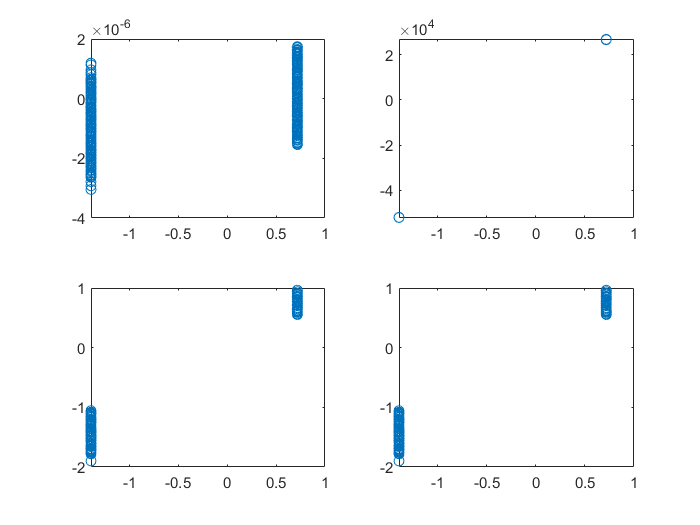

% Now, calculate the reconstructed data with the W. 
XnewW = PLSR_results.XS * PLSR_results.stats.W';

XSnew = dataset_info.explanatoryVariables * PLSR_results.stats.W;


YnewW = [ones(size(XnewW,1),1) XnewW]*PLSR_results.BETA;

% (Note that this XnewW is way too small)

% Calculate reconstructed data with the XL.
XnewXL = PLSR_results.XS * PLSR_results.XL';


YnewW = [ones(size(XnewW,1),1) XnewW]*PLSR_results.BETA; % too small
YnewYL = PLSR_results.YS * PLSR_results.YL'; % Too small
YnewXL = [ones(size(XnewXL,1),1) XnewXL]*PLSR_results.BETA; % Close
YnewXW = [ones(size(dataset_info.explanatoryVariables,1),1) dataset_info.explanatoryVariables]*PLSR_results.BETA; % Close

%  YnewXW and YnewXL are very similar. 

figure; 
subplot(2, 2, 1); plot(dataset_info.responseVariables(:,2), YnewW(:,2),  'o');
subplot(2, 2, 2); plot(dataset_info.responseVariables(:,2), YnewYL(:,2),  'o');
subplot(2, 2, 3); plot(dataset_info.responseVariables(:,2), YnewXL(:,2),  'o');
subplot(2, 2, 4); plot(dataset_info.responseVariables(:,2), YnewXW(:,2),  'o');

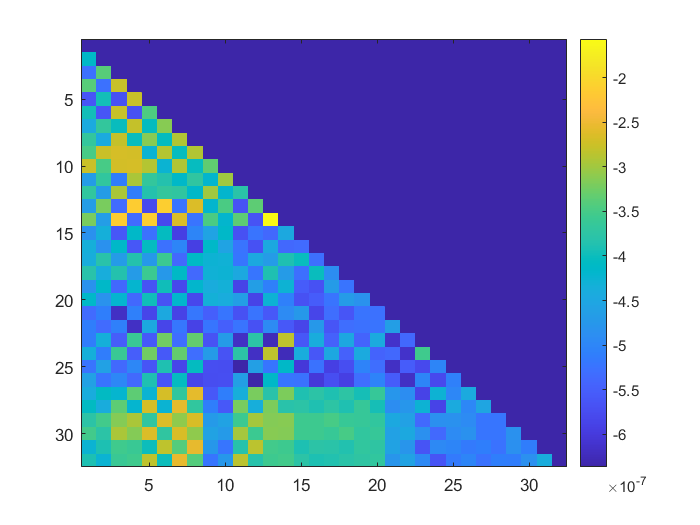

% Calculate mean difference between the two periods for XnewW
% (normalized)
mean_rest = mean(XnewW(dataset_info.responseVariables(:,2) < 0, :),1);
mean_walk = mean(XnewW(dataset_info.responseVariables(:,2) > 0, :),1);
mean_cat_diff_W = mean_walk - mean_rest;

% (Note these are also very small). 
holder(indices) = mean_cat_diff_W;
figure; imagesc(holder); colorbar;

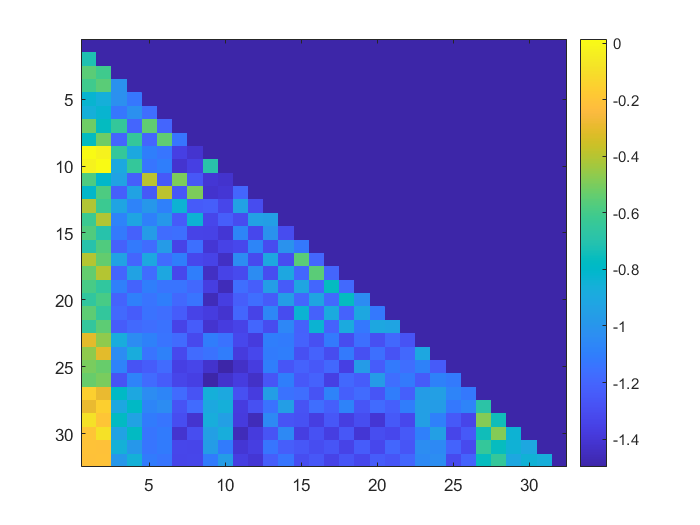

% Calculate mean difference between the two periods for XnewXL
% (not normalized)
mean_rest = mean(XnewXL(dataset_info.responseVariables(:,2) < 0, :),1);
mean_walk = mean(XnewXL(dataset_info.responseVariables(:,2) > 0, :),1);
mean_cat_diff_XL = mean_walk - mean_rest;

%
holder(indices) = mean_cat_diff_XL;
figure; imagesc(holder); colorbar;

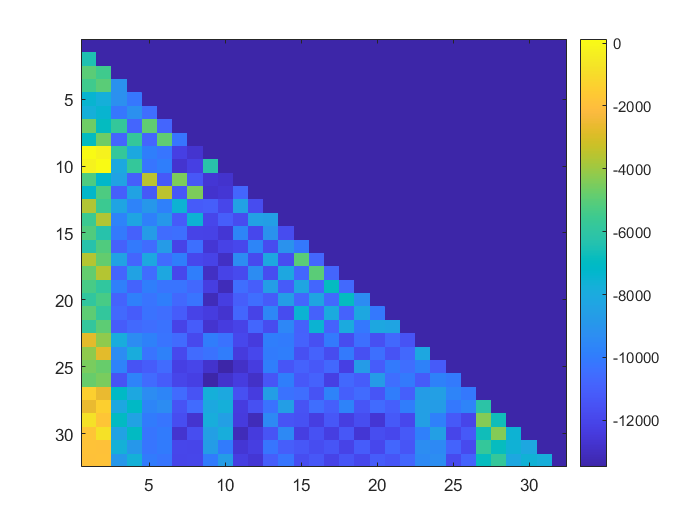

% Plot the Beta calculated with XL.
Bxl = PLSR_results.YL * PLSR_results.XL';
holder(indices) = Bxl(2,:);

% (Note the internal scale looks much more like the averages, but the
% overal scale is off).
figure; imagesc(holder); colorbar;

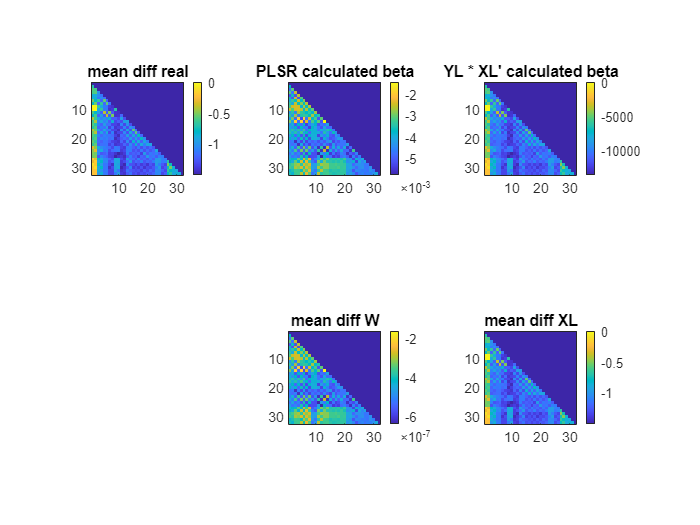

% Plot matrices next to each other.
figure; 
subplot(2, 3, 1);
holder(indices) = mean_cat_diff_real;
imagesc(holder); colorbar; title('mean diff real');axis square;

subplot(2, 3, 2);
holder(indices) = PLSR_results.BETA(2:end, 2);
imagesc(holder); colorbar; title('PLSR calculated beta'); axis square;

subplot(2, 3, 3);
holder(indices) = Bxl(2, :);
imagesc(holder); colorbar; title("YL * XL' calculated beta"); axis square;

subplot(2, 3, 6);
holder(indices) = mean_cat_diff_XL;
imagesc(holder); colorbar; title('mean diff XL'); axis square;

subplot(2, 3, 5);
holder(indices) = mean_cat_diff_W;
imagesc(holder); colorbar; title('mean diff W'); axis square;% Plot each weight.

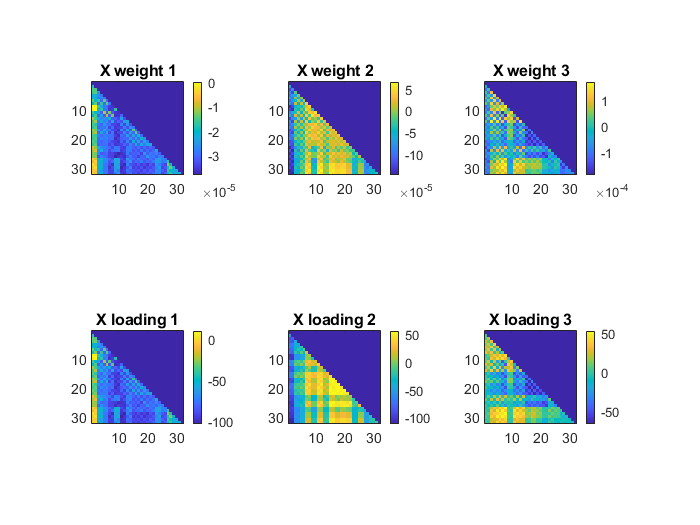


% Plot each weight
figure;
for i = 1:3
    subplot(2,3,i); 
    holder(indices) = PLSR_results.stats.W(:,i);
    imagesc(holder); colorbar; axis square; title(['X weight ' num2str(i)]);

    subplot(2,3,i + 3); 
    holder(indices) = PLSR_results.XL(:,i);
    imagesc(holder); colorbar; axis square; title(['X loading ' num2str(i)]);

end

% Calculate the "real" vs XL difference
DiffDiff = mean_cat_diff_real - mean_cat_diff_XL;


% Try to find scaling factor.
scaleDiffxlBxl = [mean_cat_diff_XL./ Bxl(2, :)]';
scaleBxlDiffxl = [Bxl(2, :) ./ mean_cat_diff_XL]';


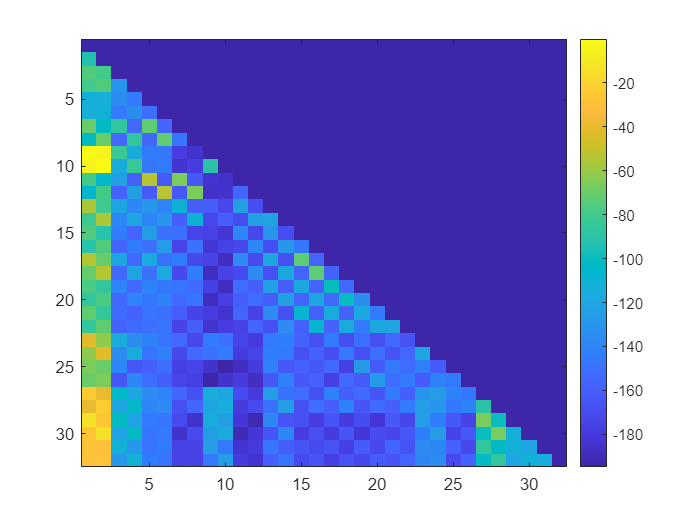

% Calculate with B scaling. 
% (THIS SHOWS THAT YES, THE PATTERN YOUR'RE SEEING CAN BE PULLED FROM W AND
% B)
B = PLSR_results.XS' * PLSR_results.YS;

beta_rescaled = PLSR_results.stats.W * B' * PLSR_results.YL';

holder(indices) = beta_rescaled( :, 2);
figure; imagesc(holder); colorbar;

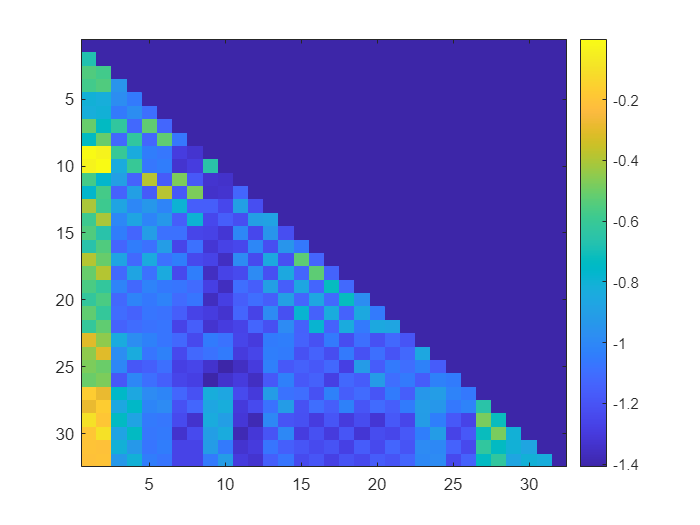

bX = ones(size(PLSR_results.XL)) * B;
bY = B * ones(size(PLSR_results.YL))';

b = beta_rescaled(:,2)./-mean(beta_rescaled(:,2));
holder(indices) = b;
figure; imagesc(holder); colorbar;



% B = T' * U


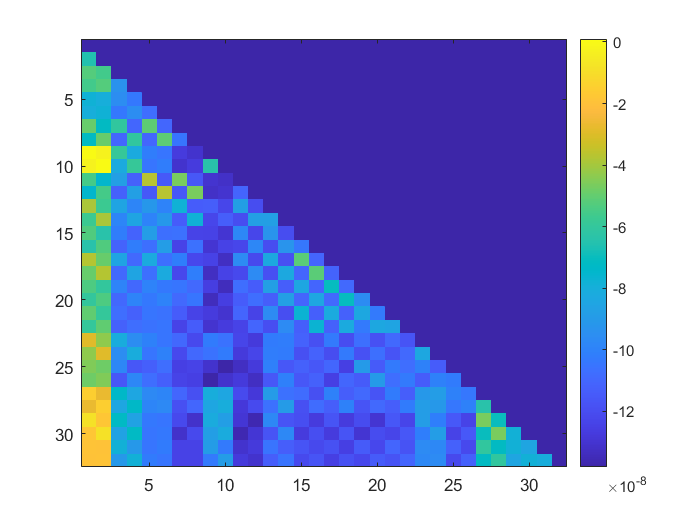

% Bpls = R (T' T)^-1 * T' * Y0; 
% Bpls = PLSR_results.stats.W * pinv(PLSR_results.XS' * PLSR_results.XS) * PLSR_results.XS' * dataset_info.responseVariables;

% Try inserting with Y scores.
Bpls = PLSR_results.stats.W * pinv(PLSR_results.XS' * PLSR_results.YS) * PLSR_results.XS' * dataset_info.responseVariables;
%Bpls = Bpls * 19003 * 496;

 holder(indices) = Bpls(:,2);
 figure; imagesc(holder); colorbar;

% Try un-normalizing the scores T.
% From https://cran.r-project.org/web/packages/pls/vignettes/pls-manual.pdf
% tnormal = t/sqrt(t't) 
% tnotnormal = tnormal .* sqrt(t't)
% B = R T' Y
 
% Unnormalize each score vector. (Can't do here. Trying to edit PLSR code
% to return it).
% for i = 1:size(PLSR_resutls.XS, 2)
%     tnormal = PLSR_results.XS(:,i);
%     tnotnormal = tnormal * sqrt(tnotnormal' * tnotnormal)
% 
% end

% Re-run PLSR 
[results.XL, results.YL, results.XS, results.YS, results.BETA, results.PCTVAR, results.MSEP, results.stats, results.MSEP_byVars, results.Tnotnormal] ...
          = plsregress_fullcode(dataset_info.explanatoryVariables, dataset_info.responseVariables, PLSR_results.ncomponents_used); 

Bpls = results.stats.W * results.Tnotnormal' * dataset_info.responseVariables;


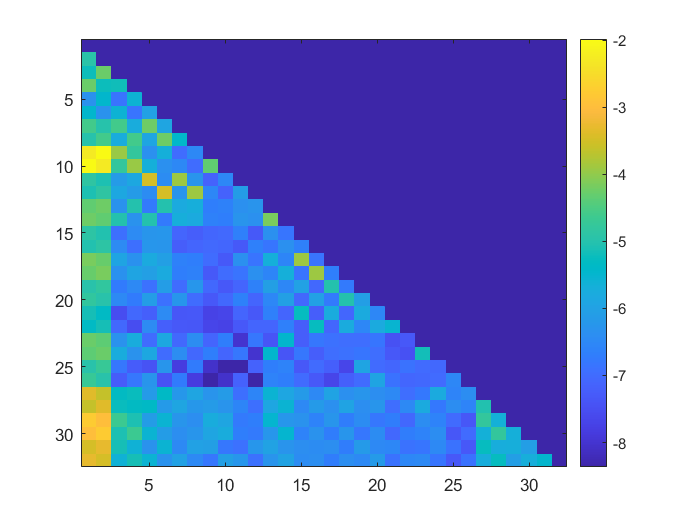


holder(indices) = Bpls(:, 2);
figure; imagesc(holder); colorbar;

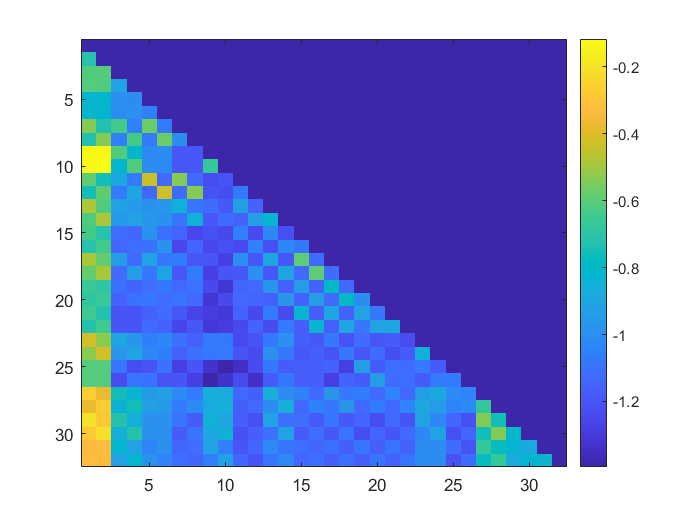

B = results.Tnotnormal' * results.YS;
% tnormal = t/sqrt(t't) 
% tnormal = results.Tnotnormal/sqrt(results.Tnotnormal' * results.Tnotnormal);
norm_factor = abs(sqrt(results.Tnotnormal' * results.Tnotnormal)); % (?)

beta_rescaled = results.XL / (norm_factor' * 3 * 2)  * results.YL'  ;
holder(indices) = beta_rescaled( :, 2);
figure; imagesc(holder); colorbar;

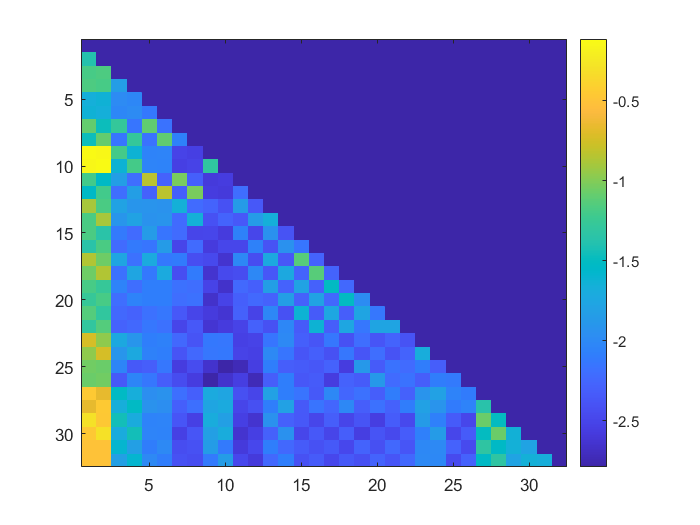


% Bpls = R (T' T)^-1 * T' * Y0; 
% Bpls = PLSR_results.stats.W * pinv(PLSR_results.XS' * PLSR_results.XS) * PLSR_results.XS' * dataset_info.responseVariables;

% Try inserting with Y scores.
Bpls = PLSR_results.stats.W  * pinv(results.Tnotnormal' * results.Tnotnormal) * (PLSR_results.YS' * PLSR_results.YS) * PLSR_results.XS' * dataset_info.responseVariables;
%Bpls = Bpls * 19003 * 496;

 holder(indices) = Bpls(:,2);
 figure; imagesc(holder); colorbar;

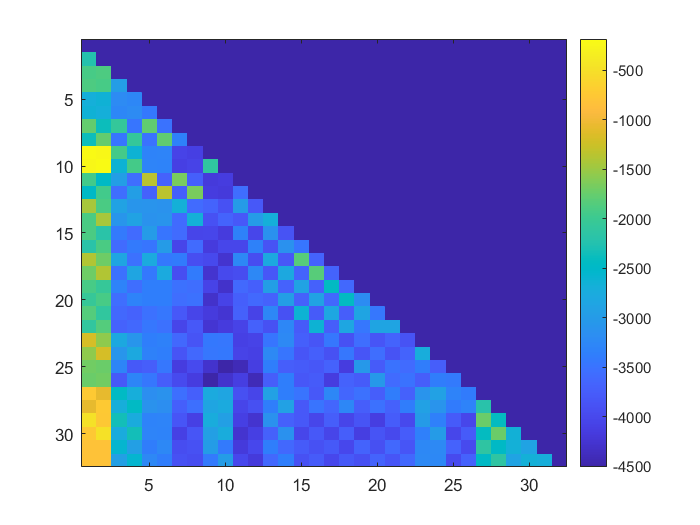

 % Bpls = R (T' T)^-1 * T' * Y0; 
% Bpls = PLSR_results.stats.W * pinv(PLSR_results.XS' * PLSR_results.XS) * PLSR_results.XS' * dataset_info.responseVariables;

% Try inserting with Y scores.
Bpls = PLSR_results.stats.W  * pinv(results.Tnotnormal' * results.Tnotnormal) *  (PLSR_results.YS' * PLSR_results.YS) * results.Tnotnormal'   * dataset_info.responseVariables;
%Bpls = Bpls * 19003 * 496;

 holder(indices) = Bpls(:,2);
 figure; imagesc(holder); colorbar;

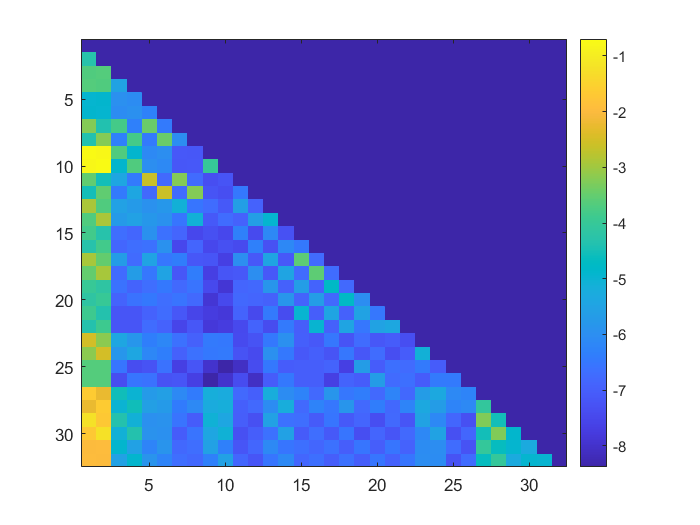

 % Bpls = R (T' T)^-1 * T' * Y0; 
% Bpls = PLSR_results.stats.W * pinv(PLSR_results.XS' * PLSR_results.XS) * PLSR_results.XS' * dataset_info.responseVariables;

% Try with XL, no Y scores.
Bpls = PLSR_results.XL * pinv(results.Tnotnormal' * results.Tnotnormal) * results.Tnotnormal'  * dataset_info.responseVariables;
%Bpls = Bpls * 19003 * 496;

 holder(indices) = Bpls(:,2);
 figure; imagesc(holder); colorbar;

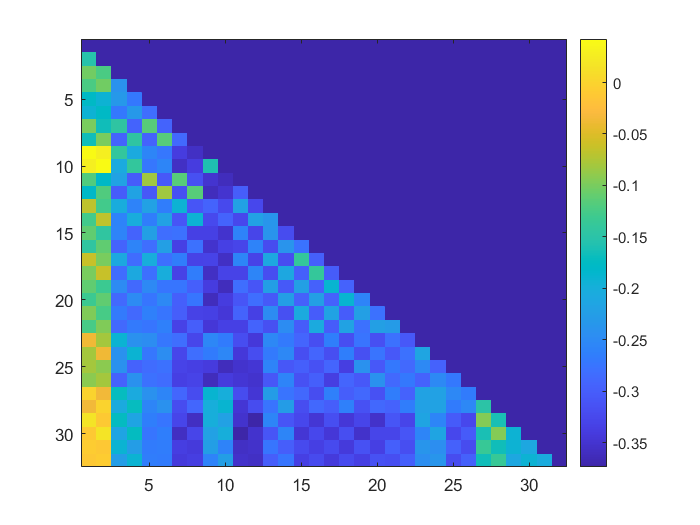

 Bpls = PLSR_results.XL  * (pinv(abs(PLSR_results.XS' * PLSR_results.YS))) * PLSR_results.YL';
 holder(indices) = Bpls(:,2);
 figure; imagesc(holder); colorbar;

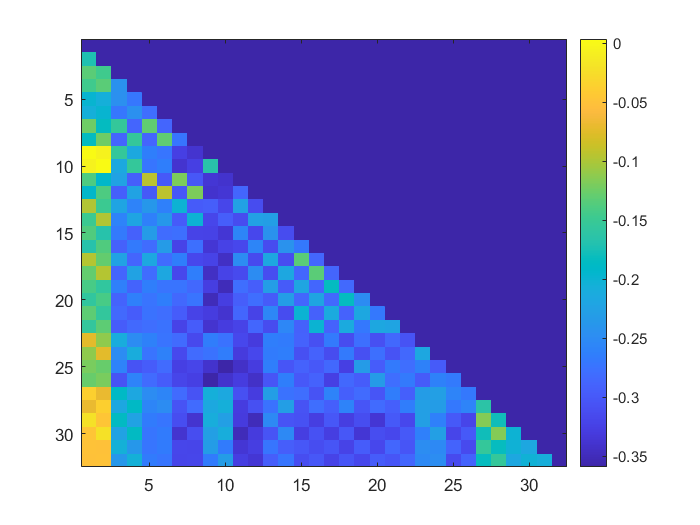

 %%
 Bpls = PLSR_results.XL / norm((PLSR_results.YS' * PLSR_results.XS )) * PLSR_results.YL';
 holder(indices) = Bpls(:,2);
 figure; imagesc(holder); colorbar;


 scale = Bpls(:,2)'./mean_cat_diff_XL;

 

 Bpls = PLSR_results.XL / sum(abs(dataset_info.responseVariables(:,2))) * 2 * PLSR_results.YL';
 holder(indices) = Bpls(:,2);
 figure; imagesc(holder); colorbar;

 scale = Bpls(:,2)'./mean_cat_diff_XL;


# Continuous

% (Using level 1 motorized start, mouse 1096).

% Load PLSR results.
load('Y:\Sarah\Analysis\Experiments\Random Motorized Treadmill\PLSR\results\level 1 continuous\Ipsa Contra\motorized_transitions_continuousVars_start\1096\PLSR_results.mat');

% Load dataset info
load('Y:\Sarah\Analysis\Experiments\Random Motorized Treadmill\PLSR\variable prep\datasets\level 1 continuous\Ipsa Contra\motorized_transitions_continuousVars_start\1096\PLSR_dataset_info.mat');


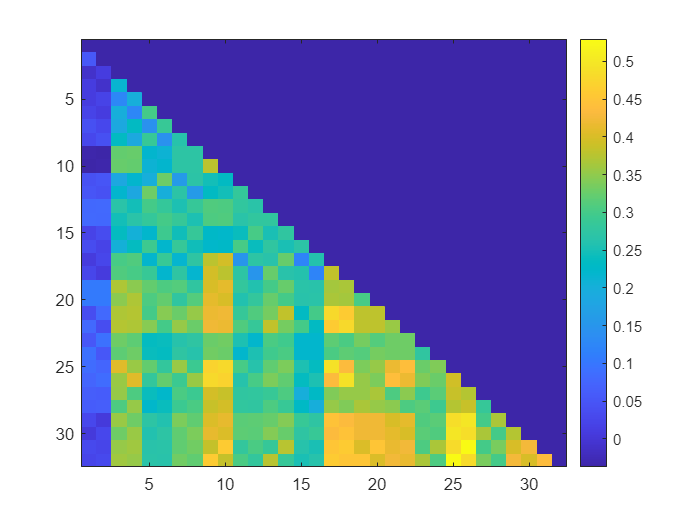

% Calculate & plot the mean difference between the two accel values using
% just averages from the original (normalized) dataset.

% (FYI, PLSR captures ~60% of the variation in the correlations for this
% comparison.)
mean_low = mean(dataset_info.explanatoryVariables(dataset_info.responseVariables(:,2) < 0, :),1);
mean_high = mean(dataset_info.explanatoryVariables(dataset_info.responseVariables(:,2) > 0, :),1);
mean_cont_diff_real = mean_high - mean_low;
holder(indices) = mean_cont_diff_real;
figure; imagesc(holder); colorbar;

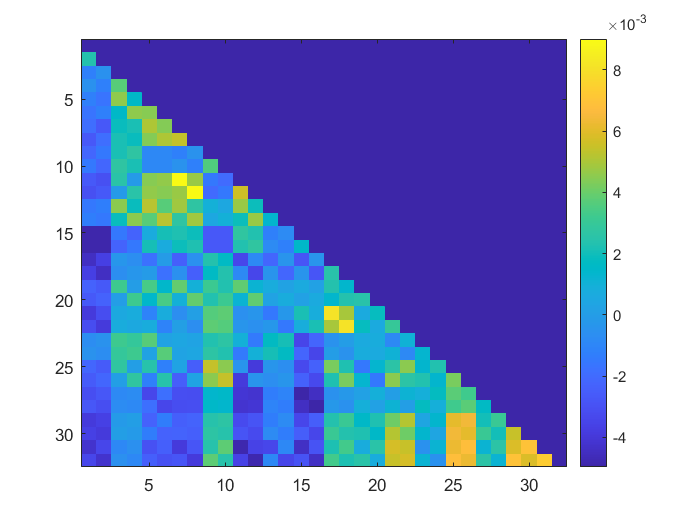

% For accel variable, plot PLSR calculated Beta.
holder = NaN(32);
indices = find(tril(ones(32), -1));

holder(indices) = PLSR_results.BETA(2:end,2);
figure; imagesc(holder); colorbar;

% Now, calculate the reconstructed data with the W. 
% XnewW = PLSR_results.XS * PLSR_results.stats.W';
% 
% % (Note that this XnewW is way too small)
% 
% % Calculate reconstructed data with the XL.
% XnewXL = PLSR_results.XS * PLSR_results.XL';
% 
% % (This matrix is at least on the right scale). 
% 
% XSnew = dataset_info.explanatoryVariables * PLSR_results.stats.W;
% 
% 
% YnewW = [ones(size(XnewW,1),1) XnewW]*PLSR_results.BETA; % too small
% YnewYL = PLSR_results.YS * PLSR_results.YL'; % Too large
% YnewXL = [ones(size(XnewXL,1),1) XnewXL]*PLSR_results.BETA; % Close
% YnewXW = [ones(size(dataset_info.explanatoryVariables,1),1) dataset_info.explanatoryVariables]*PLSR_results.BETA; % Close
% 
% %  YnewXW and YnewXL are very similar. 
% 
% figure; 
% subplot(2, 2, 1); plot(dataset_info.responseVariables(:,2), YnewW(:,2),  'o');
% subplot(2, 2, 2); plot(dataset_info.responseVariables(:,2), YnewYL(:,2),  'o');
% subplot(2, 2, 3); plot(dataset_info.responseVariables(:,2), YnewXL(:,2),  'o');
% subplot(2, 2, 4); plot(dataset_info.responseVariables(:,2), YnewXW(:,2),  'o');

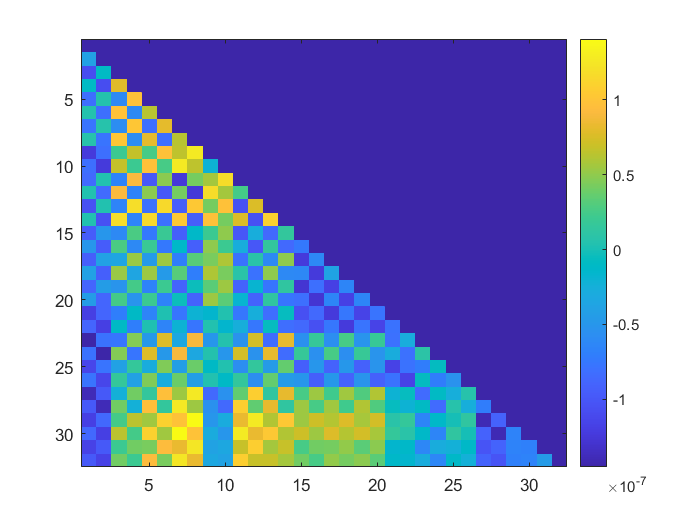

% Calculate mean difference between the two accel values for XnewW
% (normalized)
mean_low = mean(XnewW(dataset_info.responseVariables(:,2) < 0, :),1);
mean_high = mean(XnewW(dataset_info.responseVariables(:,2) > 0, :),1);
mean_cont_diff_W = mean_high - mean_low;

% (Note these are also very small). 
holder(indices) = mean_cont_diff_W;
figure; imagesc(holder); colorbar;

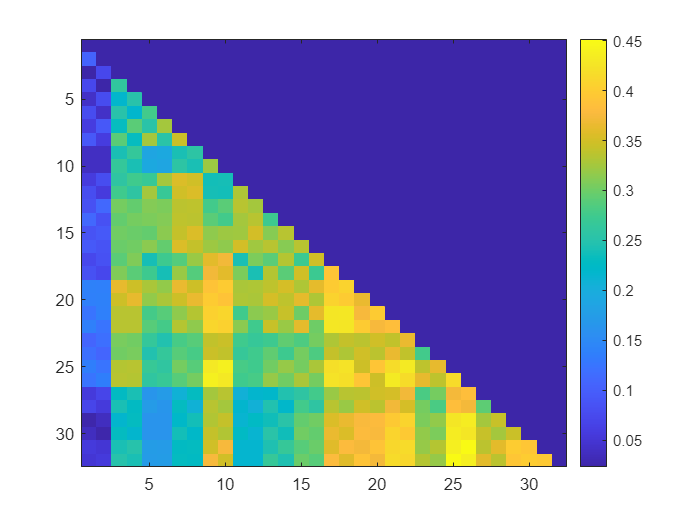

% Calculate mean difference between the two accel values for XnewXL (not
% normalized)

% Calculate reconstructed data with the XL.
XnewXL = PLSR_results.XS * PLSR_results.XL';
mean_low = mean(XnewXL(dataset_info.responseVariables(:,2) < 0, :),1);
mean_high = mean(XnewXL(dataset_info.responseVariables(:,2) > 0, :),1);
mean_cont_diff_XL = mean_high - mean_low;

% (Note these more closely match the plain old average in overall scale & also internal gradient/scale)
holder(indices) = mean_cont_diff_XL;
figure; imagesc(holder); colorbar;

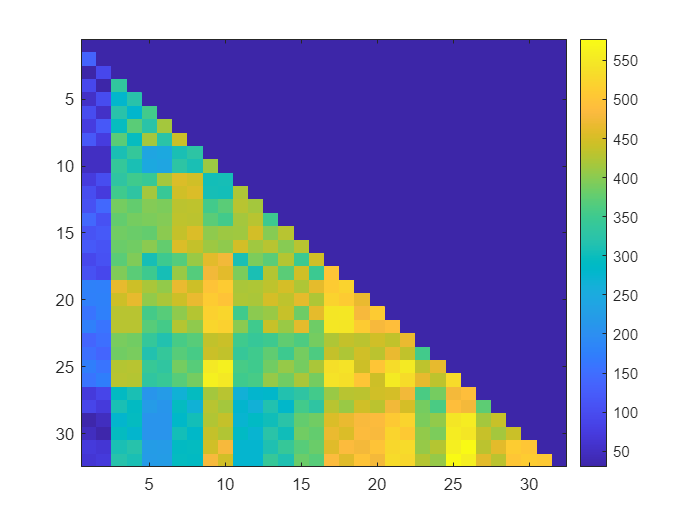

% Plot the Beta calculated with XL.
Bxl = PLSR_results.YL * PLSR_results.XL';
holder(indices) = Bxl(2,:);

% (Note the internal scale looks much more like the averages, but the
% overal scale is off).
figure; imagesc(holder); colorbar;

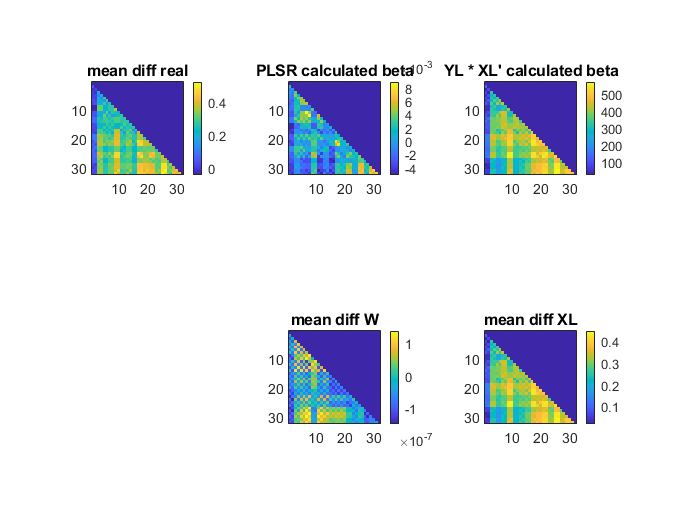

% Plot matrices next to each other.
figure; 
subplot(2, 3, 1);
holder(indices) = mean_cont_diff_real;
imagesc(holder); colorbar; title('mean diff real');axis square;

subplot(2, 3, 2);
holder(indices) = PLSR_results.BETA(2:end, 2);
imagesc(holder); colorbar; title('PLSR calculated beta'); axis square;

subplot(2, 3, 3);
holder(indices) = Bxl(2, :);
imagesc(holder); colorbar; title("YL * XL' calculated beta"); axis square;

subplot(2, 3, 6);
holder(indices) = mean_cont_diff_XL;
imagesc(holder); colorbar; title('mean diff XL'); axis square;

subplot(2, 3, 5);
holder(indices) = mean_cont_diff_W;
imagesc(holder); colorbar; title('mean diff W'); axis square;

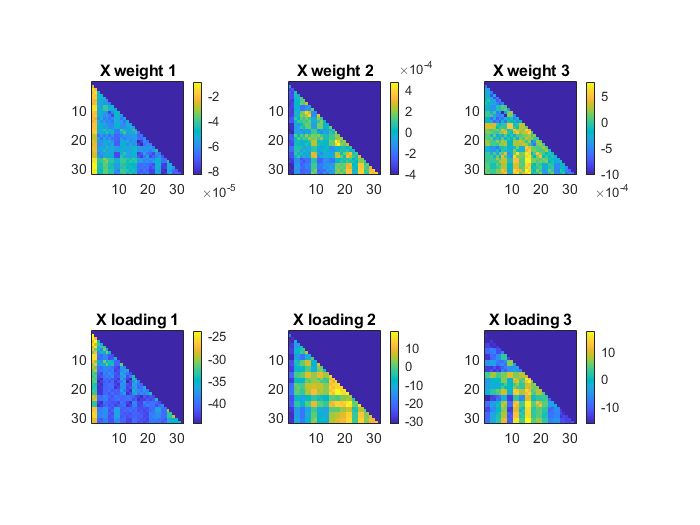

% Plot each weight.
figure;
for i = 1:3
    subplot(2,3,i); 
    holder(indices) = PLSR_results.stats.W(:,i);
    imagesc(holder); colorbar; axis square; title(['X weight ' num2str(i)]);

    subplot(2,3,i + 3); 
    holder(indices) = PLSR_results.XL(:,i);
    imagesc(holder); colorbar; axis square; title(['X loading ' num2str(i)]);

end


% Try to find the difference in scale.
% scaleDiffBxl = mean_cont_diff ./ Bxl(2, :);
% scaleBxlDiff = Bxl(2, :) ./  mean_cont_diff;
% scaleSigma = dataset_info.zscoring.responseVariables.sigma(2) ./ dataset_info.zscoring.explanatoryVariables.sigma;
% 
% all_scales = [scaleDiffBxl', scaleBxlDiff', PLSR_results.BETA(2:end, 2) scaleSigma'];
% 


% % Try running PLSR on not-normalized datasets.
% 
% % Un-normalize.
% responseVariables = dataset_info.responseVariables .* dataset_info.zscoring.responseVariables.sigma + dataset_info.zscoring.responseVariables.mu;
% explanatoryVariables = dataset_info.explanatoryVariables .* dataset_info.zscoring.explanatoryVariables.sigma + dataset_info.zscoring.explanatoryVariables.mu;
% 
% % Run PLSR (just use number of components used from previous results).
%  [results.XL, results.YL, results.XS, results.YS, results.BETA, results.PCTVAR, results.MSEP, results.stats, results.MSEP_byVars] ...
%           = plsregress_fullcode(explanatoryVariables, responseVariables, PLSR_results.ncomponents_used); 
% 
% % Plot new calculated beta.
% holder(indices) = results.BETA(2:end,2);
% figure; imagesc(holder); colorbar;
% % (this still looks like the normalized PLSR beta, probably because PLSR
% % removes the mean & the sigmas are all very similar).
% 
% % Try calculating XnewXL from this
% XnewXL = results.XS * results.XL';
% 
% % Calculate mean difference between the two accel values for XnewW
% % (normalized)
% mean_low = mean(XnewXL(responseVariables(:,2) < 0, :),1);
% mean_high = mean(XnewXL(responseVariables(:,2) > 0, :),1);
% mean_cont_diff = mean_high - mean_low;
% 
% % 
% holder(indices) = mean_cont_diff;
% figure; imagesc(holder); colorbar;
% Get B (see below) for this set
% B = results.XS' * results.YS;
% 
% Bpls = pinv(results.XL') * B * results.YL'; 
% holder(indices) = Bpls(:,2);
% figure; imagesc(holder); colorbar;

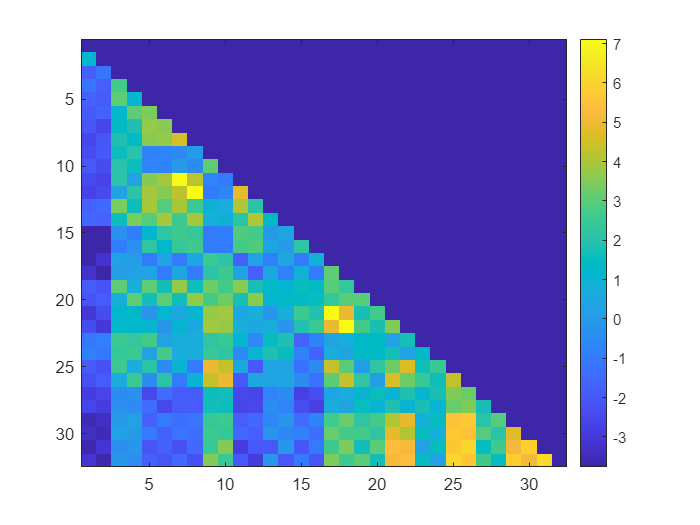

% Try re-calculating beta (from "Partial Least Squares (PLS) methods for
% neuroimaging" tutorial paper).

% Find B
% B = T'U
% T = "matrix of latent variables" for X; # of observations by # of components
% U = "the latent variables for Y";  # of observations by # of components
% B = PLSR_results.XS' * PLSR_results.YS;
% 
% % Find Bpls.
% % Bpls = pinv(P') * BC' 
% % C = "factor loadings of Y" ; # y variables by # components
% % P = "loadings for X"; # x variables by # components
% Bplspinv = pinv(PLSR_results.XL') * B * PLSR_results.YL'; 
% Bpls = PLSR_results.XL * B * PLSR_results.YL'; 
% 
% % Plot 
% figure
% holder(indices) = Bplspinv(:,2);
% subplot(1,2,1); imagesc(holder); colorbar;
% holder(indices) = Bpls(:,2);
% subplot(1,2,2); imagesc(holder); colorbar;


B =  PLSR_results.XS' *  PLSR_results.YS;
beta_rescaled = PLSR_results.stats.W * B' * PLSR_results.YL';

holder(indices) = beta_rescaled( :, 2);
figure; imagesc(holder); colorbar;

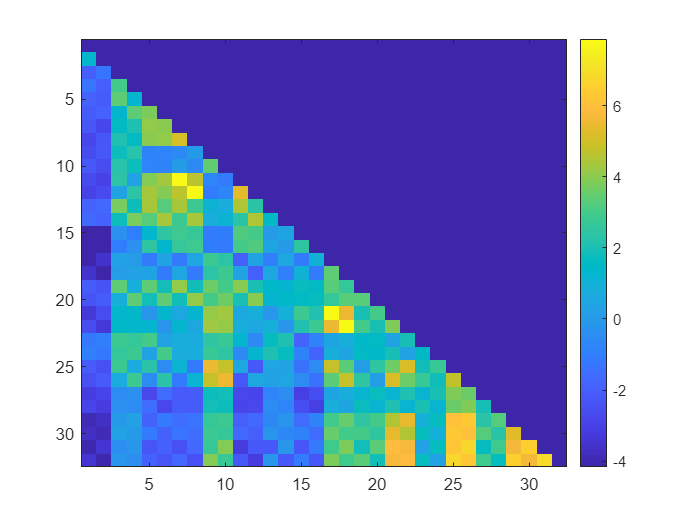

bX = ones(size(PLSR_results.XL)) * B;
bY = B * ones(size(PLSR_results.YL))';

b = beta_rescaled(:,2)./mean(beta_rescaled(:,2), 1);
holder(indices) = b;
figure; imagesc(holder); colorbar;

% From original SIMPLS paper
% Bpls = R * T- * Y0 = R * Q'
% R = weights
% T = "scores"  = X * R (where X is the deflated X at each step)


% Different B combinations
% % BxlB = (PLSR_results.YL) * pinv(B) * (PLSR_results.XL)';
% % holder(indices) = BxlB(2,:);
%figure; imagesc(holder); colorbar;

% BxlB = (PLSR_results.YL) * pinv(B') * (PLSR_results.XL)';
% holder(indices) = BxlB(2,:);
% figure; imagesc(holder); colorbar
% 

% BxlB = (PLSR_results.YL) / B * (PLSR_results.XL)';
% holder(indices) = BxlB(2,:);
% figure; imagesc(holder); colorbar
% 
% 

% BxlB = (PLSR_results.YL) * pinv(B') * (PLSR_results.XL)';
% holder(indices) = BxlB(2,:);
% figure; imagesc(holder); colorbar
% % Do again, but with Bpls from W
% BplsWpinv = pinv(PLSR_results.stats.W') * pinv(B) * PLSR_results.YL'; 
% BplsW = PLSR_results.stats.W * B * PLSR_results.YL'; 
% 
% % Plot 
% figure; 
% holder(indices) = BplsWpinv(:,2);
% subplot(1,2,1); imagesc(holder); colorbar;
% holder(indices) = BplsW(:,2);
% subplot(1,2,2); imagesc(holder); colorbar;

% 
% 
% % Find scaling difference between abouve Bxl and this one.
% scaleBxlBpls = Bxl'./ Bpls;
% scaleBplsBxl= Bpls ./ Bxl';
% scaleBplsDiff = Bpls(:,2)./mean_cont_diff';
% scaleDiffBpls = mean_cont_diff' ./ Bpls(:,2);
% weightsums = sum(PLSR_results.stats.W,2);
% all_scales = [mean_cont_diff',Bxl(2,:)', PLSR_results.BETA(2:end, 2) scaleDiffBxl', scaleBxlDiff', scaleSigma', scaleBplsBxl(:,2), scaleBplsDiff, scaleDiffBpls, weightsums ];
% 



% Bpls = RQ'
% with non-normalized Y loadings  Q = Y' T; 
% Bpls = R * (Y' * T)';
% T = X * R
% Bpls = R * (Y' * X * R)'
% Bpls = Y' * X * R
 % 496 x 3, ( 4 x n, n * 496,  496 *3)'
% Bpls = PLSR_results.stats.W * (dataset_info.responseVariables' *  dataset_info.explanatoryVariables * PLSR_results.stats.W)';
% 
% holder(indices) = Bpls(:,2);
% figure; imagesc(holder); colorbar;
Bpls = PLSR_results.XL* pinv(B') * (dataset_info.responseVariables' *  dataset_info.explanatoryVariables * PLSR_results.stats.W )';

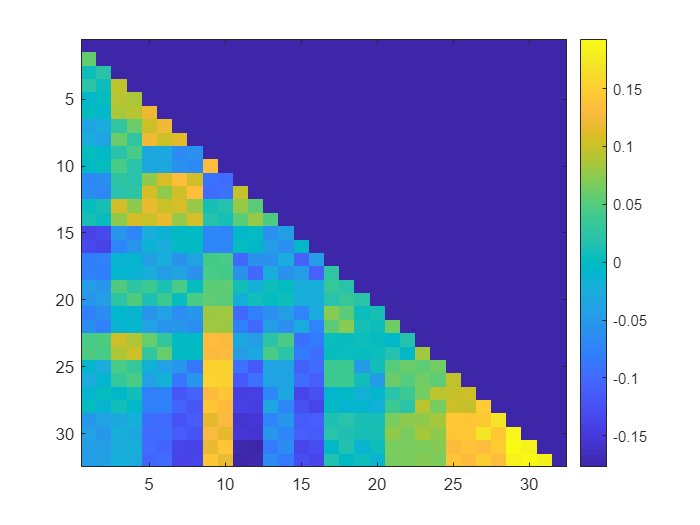


holder(indices) = Bpls(:,2);
figure; imagesc(holder); colorbar;

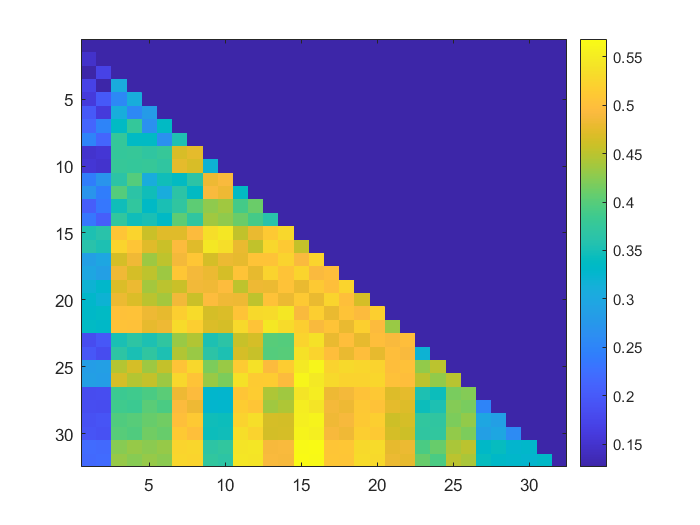

%Beta = Bpls ./ bY;
B = PLSR_results.XS' * PLSR_results.YS;
beta_rescaled = PLSR_results.XL / B * PLSR_results.YL';
holder(indices) = beta_rescaled(:,2);
figure; imagesc(holder); colorbar;


% Bpls = R (T' T)^-1 * T' * Y0; 
% Bpls = PLSR_results.stats.W * pinv(PLSR_results.XS' * PLSR_results.XS) * PLSR_results.XS' * dataset_info.responseVariables;

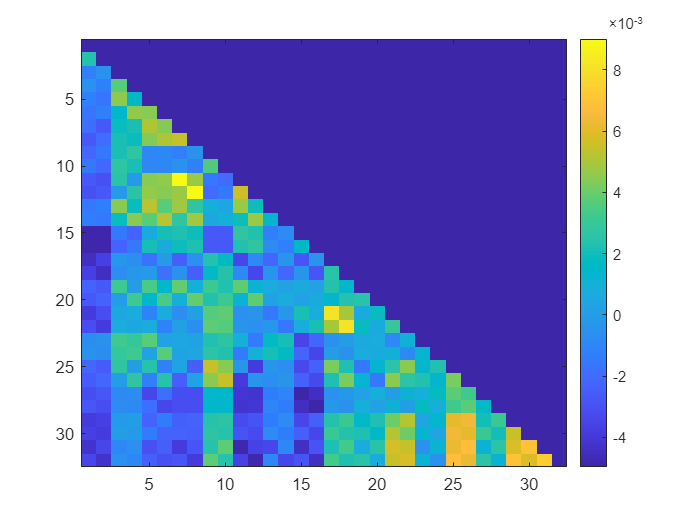


% Try inserting with Y scores.
Bpls = PLSR_results.stats.W * pinv(PLSR_results.XS' * PLSR_results.XS) * PLSR_results.XS' * dataset_info.responseVariables;
%Bpls = Bpls * 19003 * 496;

 holder(indices) = Bpls(:,2);
 figure; imagesc(holder); colorbar;

%%


% Try un-normalizing the scores T.
% From https://cran.r-project.org/web/packages/pls/vignettes/pls-manual.pdf
% tnormal = t/sqrt(t't) 
% tnotnormal = tnormal .* sqrt(t't)
% B = R T' Y
 
% Unnormalize each score vector. (Can't do here. Trying to edit PLSR code
% to return it).
% for i = 1:size(PLSR_resutls.XS, 2)
%     tnormal = PLSR_results.XS(:,i);
%     tnotnormal = stnormal * sqrt(tnotnormal' * tnotnormal)
% 
% end

% Re-run PLSR 
[results.XL, results.YL, results.XS, results.YS, results.BETA, results.PCTVAR, results.MSEP, results.stats, results.MSEP_byVars, results.Tnotnormal] ...
          = plsregress_fullcode(dataset_info.explanatoryVariables, dataset_info.responseVariables, PLSR_results.ncomponents_used); 

Bpls = results.stats.W * results.Tnotnormal' * dataset_info.responseVariables;

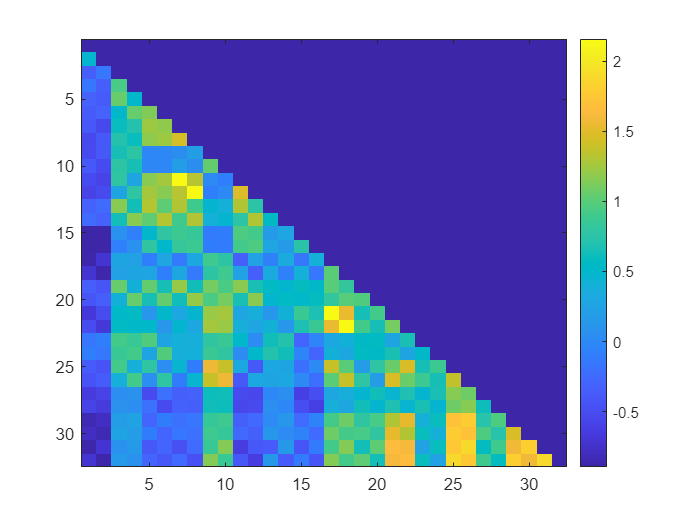


holder(indices) = Bpls(:, 2);
figure; imagesc(holder); colorbar;

B = results.Tnotnormal' * results.YS;
% tnormal = t/sqrt(t't) 
% B = results.Tnotnormal' * results.YS;

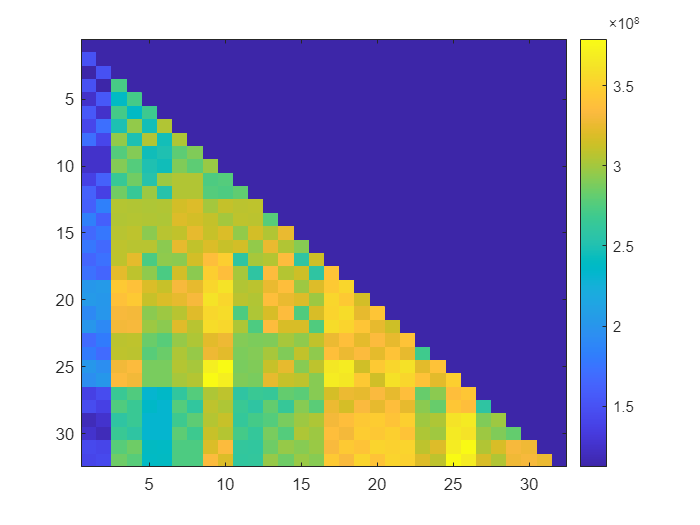


% beta_rescaled = (dataset_info.explanatoryVariables' * results.Tnotnormal)'  * results.YL';
beta_rescaled = results.XL * B * results.YL';
holder(indices) = beta_rescaled( :, 2);
figure; imagesc(holder); colorbar;

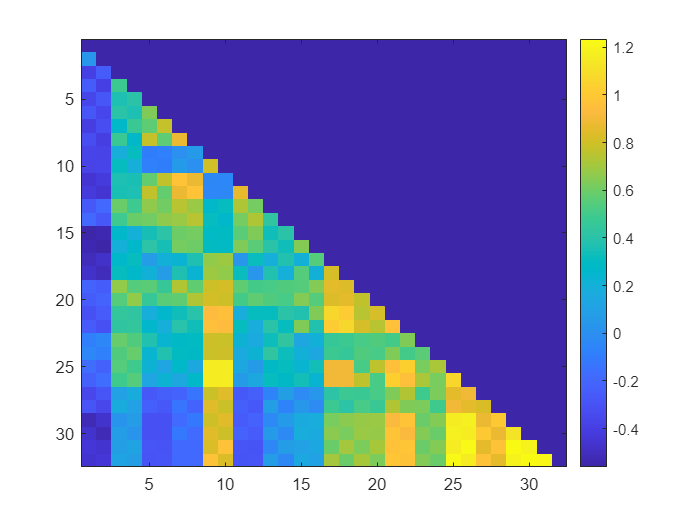

% % Bpls = R (T' T)^-1 * T' * Y0; 
 Bpls = PLSR_results.XL * pinv(results.Tnotnormal' * results.Tnotnormal) * results.Tnotnormal' * dataset_info.responseVariables;
holder(indices) = Bpls( :, 2);
figure; imagesc(holder); colorbar;

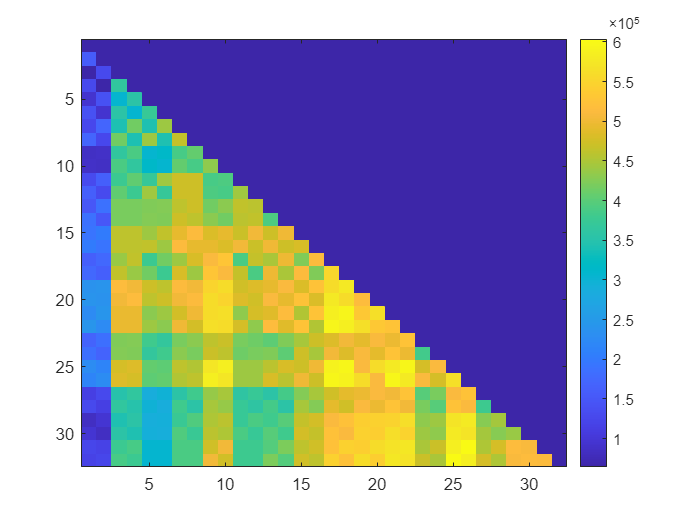




B = results.Tnotnormal' * results.YS;
% tnormal = t/sqrt(t't) 
% tnormal = results.Tnotnormal/sqrt(results.Tnotnormal' * results.Tnotnormal);
norm_factor = abs(sqrt(results.Tnotnormal' * results.Tnotnormal)); % (?)

beta_rescaled = results.XL * (B / norm_factor)' * results.YL';
holder(indices) = beta_rescaled( :, 2);
figure; imagesc(holder); colorbar;

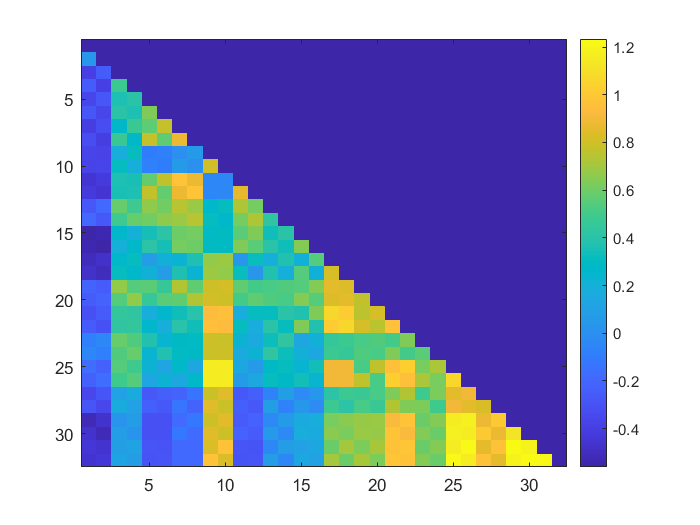

beta_rescaled = results.XL  / (norm_factor)' * results.YL';
holder(indices) = beta_rescaled( :, 2);
figure; imagesc(holder); colorbar;

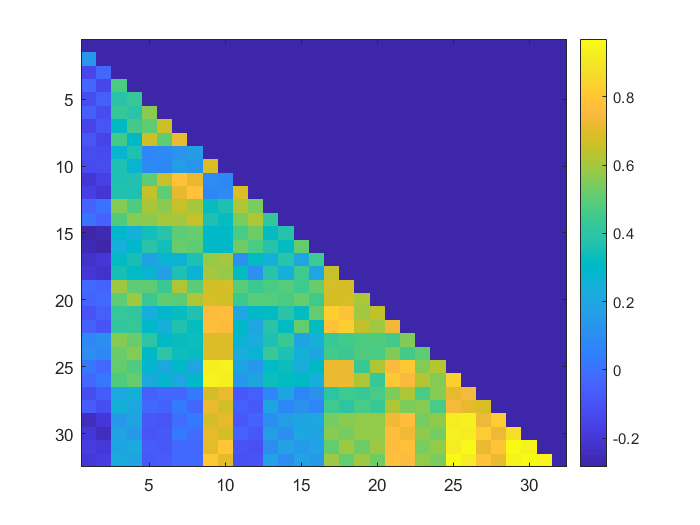


 Bpls = PLSR_results.XL / abs(PLSR_results.XS' * PLSR_results.YS) * PLSR_results.YL';
 holder(indices) = Bpls(:,2);
 figure; imagesc(holder); colorbar;

 %%

 Bpls = PLSR_results.XL * pinv(PLSR_results.XS' * results.Tnotnormal) * PLSR_results.YL';
 holder(indices) = Bpls(:,2);
 figure; imagesc(holder); colorbar;

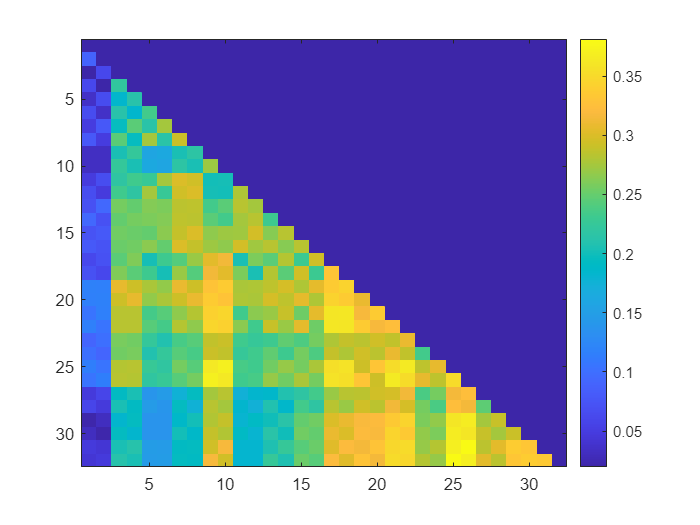


 %%
  Bpls = PLSR_results.XL / norm(PLSR_results.XS' * PLSR_results.YS ) * PLSR_results.YL';
 holder(indices) = Bpls(:,2);
 figure; imagesc(holder); colorbar;


 %%
 scale = Bpls(:,2)'./mean_cont_diff_XL;

 

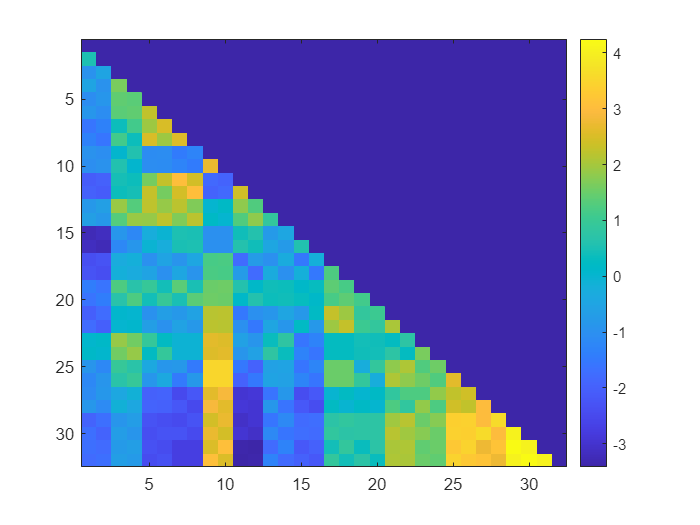

 Bpls = PLSR_results.XL /(results.Tnotnormal' * results.Tnotnormal / norm((results.Tnotnormal ))) * PLSR_results.YL';
 holder(indices) = Bpls(:,2);
 figure; imagesc(holder); colorbar;

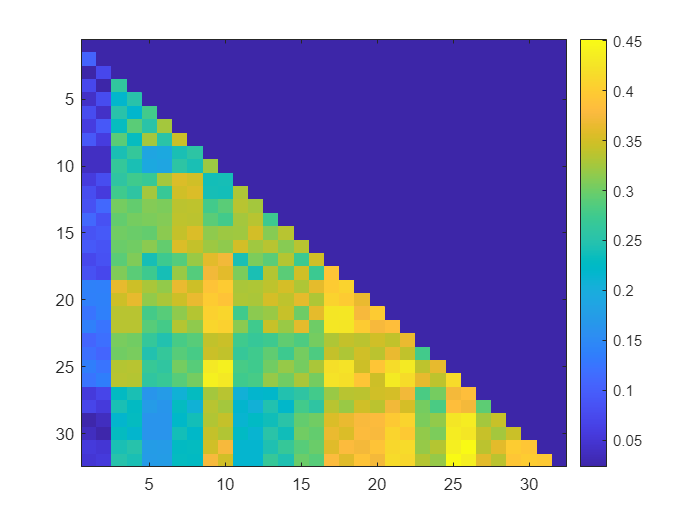

 Bpls = PLSR_results.XL * PLSR_results.YL' ./ sum(abs(dataset_info.responseVariables), 1) * 2;
 holder(indices) = Bpls(:,2);
 figure; imagesc(holder); colorbar;

 scale = Bpls(:,2)'./mean_cont_diff_XL;